# wing design

clc
clear all

## parameters

Mach=0.7

Mach = 0.7000

Weight=120000/0.4536                      %lb

Weight = 2.6455e+05

Wing_loading=70                  %lb/ft2

Wing_loading = 70

Wing_area=Weight/Wing_loading     %ft^2   300/(0.3048^2 ) 

Wing_area = 3.7793e+03

AR=8.5                        % what we set     (一般大型運輸機AR在7~10之間)

AR = 8.5000

Sweep_Angle=30*pi/180         %rad      (一般大型運輸機的後掠角介於25度到45度之間)

Sweep_Angle = 0.5236

Dihedral_angle=6              %rad      (一般大概都在8度以下)

Dihedral_angle = 6

Taper_ratio = 0.2*AR^(0.25)*(cos(Sweep_Angle))^2   

Taper_ratio = 0.2561

Span_w=(AR*Wing_area)^0.5   %ft

Span_w = 179.2316

c_r=Wing_area*2/Span_w/(1+Taper_ratio)   %ft  root chord 8.487

c_r = 33.5733

c_t = c_r*Taper_ratio                 %ft  tip chord

c_t = 8.5988


MAC = 2/3*c_r*(1+Taper_ratio+Taper_ratio^2)/(1+Taper_ratio)      %Mean Aerodynamic Chord

MAC = 23.5511

## cruise


Weight_cruise=105356/0.4536             %lb  average of cruise weight

Weight_cruise = 2.3227e+05

V_cruise=667.6                  %ft/s

V_cruise = 667.6000

d=7.38*10^-4                           %slug/ft^3 @35000ft

d = 7.3800e-04

CL_cruise=2*Weight_cruise/(d*(V_cruise^2)*Wing_area)/0.95     % for wing only /0.95

CL_cruise = 0.3934

Cl_cruise=CL_cruise/0.9               % convert to 2D /0.9

Cl_cruise = 0.4371

## take-off

W_TO=117612/0.4536          %lb

W_TO = 2.5929e+05

V_TO=235          %ft/s

V_TO = 235

do=0.002377           %slug/ft^3

do = 0.0024

CLmax_TO=(2*W_TO)/(do*(V_TO^2)*Wing_area)/0.9  %for wing only / 0.9

CLmax_TO = 1.1614

## Landing

Wmax_l=70428/0.4536                     %lb

Wmax_l = 1.5526e+05

V_l=235                                 %ft/s

V_l = 235

do=0.002377                             %slug/ft^3

do = 0.0024

CLmax_l=(2*Wmax_l)/(do*(V_l^2)*Wing_area)/0.9  %for wing only / 0.9

CLmax_l = 0.6955

## high lift de0 vices

%for slat
%cf_to_c=0.15                  %the ratio of the leading edge slat chord to the wing chord
%bslat_to_be=0.75              %the ratio of the total slat span to the exposed wing span
%dCLmax_slat=1.28*((cf_to_c)/0.18)*((bslat_to_be)^2)*(cos(Sweep_Angle))^2         %for slat

%for 2 slot flap  (25% chord flaps at the 50 deg landing flap)
k1=0.8    %20% chord

k1 = 0.8000

k2=0.5   %20deg

k2 = 0.5000

CLmax_base=1.6        %(25% chord flaps at the 50 deg landing flap)

CLmax_base = 1.6000

dCLmax_flap=k1*k2*CLmax_base

dCLmax_flap = 0.6400


Sw_2_S=(2-(1-Taper_ratio)*(0.1+0.3))*(0.3-0.1)/(1+Taper_ratio)   %0.1~0.3 flap span

Sw_2_S = 0.2711

K=(1-0.08*(cos(Sweep_Angle))^2)*(cos(Sweep_Angle))^0.75

K = 0.8439


Clmax_flap=dCLmax_flap*K*Sw_2_S

Clmax_flap = 0.1464

## Airfoil thickness

%Mcrit_3D=0.7
%Mcrit_2D=Mcrit_3D*(cos(Sweep_Angle))^0.5  %Mcrit_2D為巡航時馬赫數
%M_star=1                            % M* is 1.0 for conventional airfoils
%t_to_c=0.3*((1-((5+Mcrit_2D^2)/(5+M_star^2))^(3.5))*(1-Mcrit_2D^2)^(0.5)/(Mcrit_2D^2))^(2/3) %0.1~0.15之間
t_to_c=0.12

t_to_c = 0.1200

## Convert to 3-D


beta=(1-Mach^2)^(1/2)

beta = 0.7141

%Cl_frad=(15)*180/pi
dCl_to_dalpha=2*pi

dCl_to_dalpha = 6.2832

CL_alpha=(2*pi*AR)/(2+(4+(AR^2*beta^2*(1+(tan(Sweep_Angle)/beta)^2))/(dCl_to_dalpha/(2*pi))^2)^0.5)

CL_alpha = 5.3099

zeroL_AOA=(-3)

zeroL_AOA = -3

aoa=-5:0.25:10;
CL_curve=(CL_alpha*pi/180)*(aoa-zeroL_AOA)

CL_curve =    -0.1854   -0.1622   -0.1390   -0.1158   -0.0927   -0.0695   -0.0463   -0.0232         0    0.0232    0.0463    0.0695    0.0927    0.1158    0.1390    0.1622    0.1854    0.2085    0.2317    0.2549    0.2780    0.3012    0.3244    0.3475    0.3707    0.3939    0.4170    0.4402    0.4634    0.4865    0.5097    0.5329    0.5561    0.5792    0.6024    0.6256    0.6487    0.6719    0.6951    0.7182    0.7414    0.7646    0.7877    0.8109    0.8341    0.8573    0.8804    0.9036    0.9268    0.9499


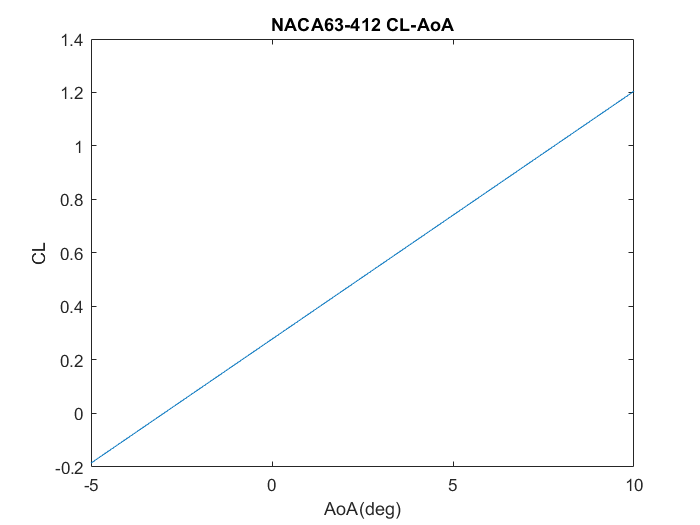


plot(aoa,CL_curve)
title('NACA63-412 CL-AoA')
xlabel('AoA(deg)')
ylabel('CL')